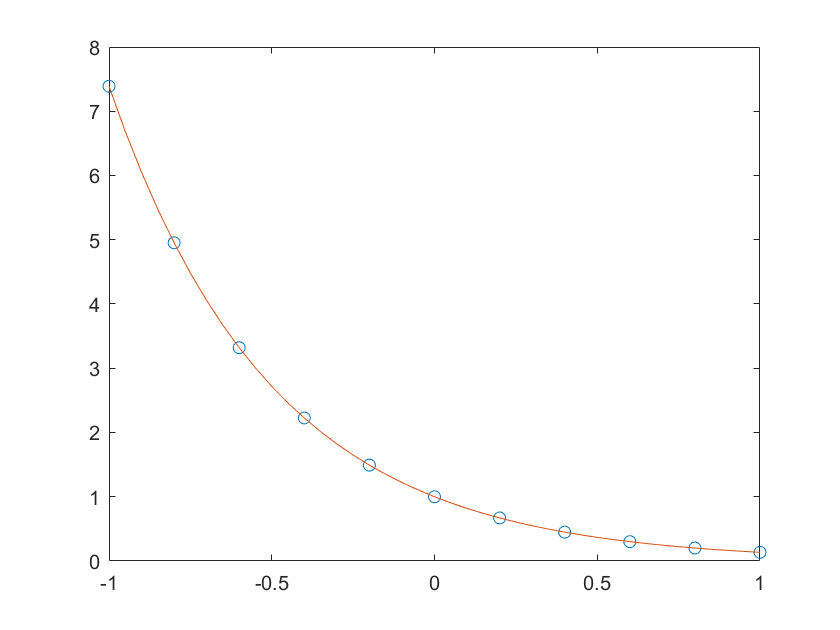

% x/y_sample_even/cheb: the sample points to generate the polynomial
% x/y_test_even/cheb: generated polynomial f(x,y)
% x/y_res_even/cheb: exponential function exp(x,y)
x_test = -1:.05:1; 

% generate a degree n polynomial with evenly spaced points 
n = 10;
x_sample_even = (-1 : 2/n : 1);
y_sample_even = exp(-2 * x_sample_even);
c_even = newtdd(x_sample_even, y_sample_even, n + 1);
y_res_even = exp(-2 * x_test);
y_test_even= nest(n, c_even, x_test, x_sample_even); 

n = 11; 
% generate a degree n-1 polynomial with Chebyshev points 
x_sample_cheb = cos((1:2:2*n-1)*pi/(2*n));
y_sample_cheb = exp(-2 * x_sample_cheb); 
c_cheb = newtdd(x_sample_cheb, y_sample_cheb, n); 
y_res_cheb = exp(-2 * x_test);
% x_test has been defined above
y_test_cheb = nest(n-1, c_cheb, x_test, x_sample_cheb); 
  
% polynomials -- even points  
figure(1) 
plot(x_sample_even, y_sample_even, 'o',x_test, y_test_even)

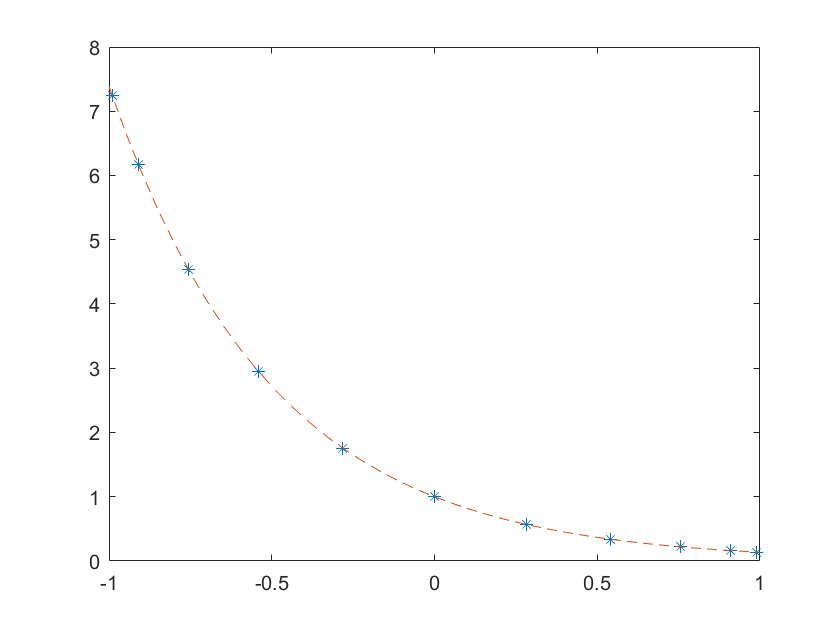

% polynomials -- Chebyshev points
figure(2) 
plot(x_sample_cheb,y_sample_cheb,'*',x_test,y_test_cheb,'--') 

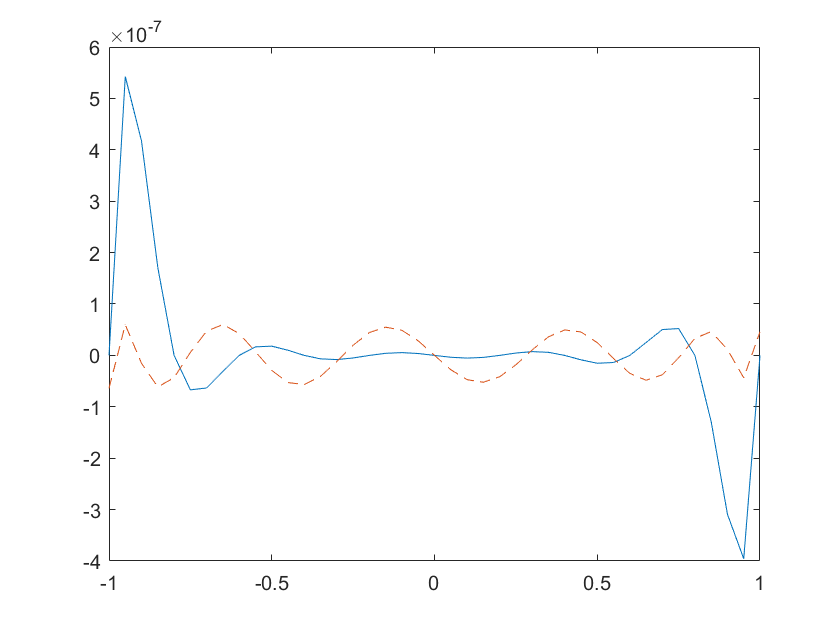

  
% compute empirical interpolation errors -- even points
h_even = y_test_even - y_res_even;
% empirical interpolation errors -- Chebyshev points
h_cheb = y_test_cheb - y_res_cheb; 
plot(x_test, h_even)
hold on
plot(x_test, h_cheb,'--') 